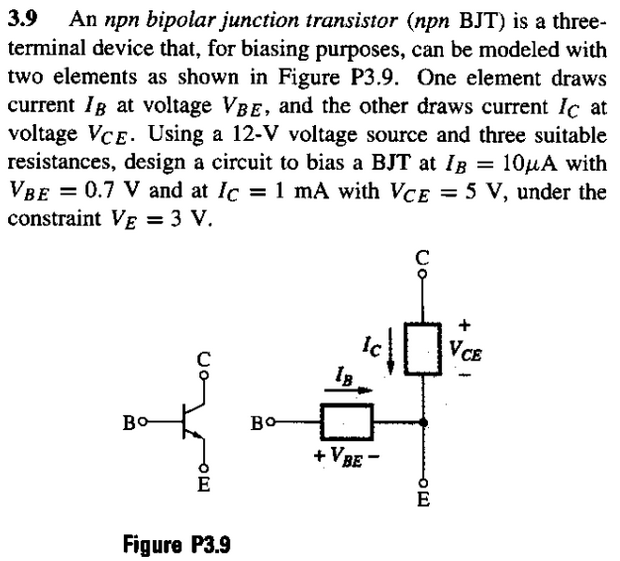

primero anotamos los datos que nos entrega el problema

clc, clear, close all
format short g

I_B = 10e-6;
V_BE = 0.7;
r1 = V_BE/I_B

r1 =         70000



I_C = 1e-3;
V_CE = 5;
r2 = V_CE/I_C

r2 =         5000


De acuerdo con los datos que nos dan y calculados los valores de resistencia que componen el modelo de BJT. Ahora sabemos por la LCK que la corriente I_E = I_B + I_C, y sabemos el potencial en E, por lo que podemos calcular el valor de resistencia de polarizacion del emisor:

I_E = I_B + I_C

I_E =       0.00101


V_E = 3;

r_E = V_E/I_E

r_E =        2970.3


Para saber los valores de r_C y r_B, podemos hacerlo analizando el circuito, para ello, lo visualizamos con sus incognitas y los datos que hasta ahora tenemos:

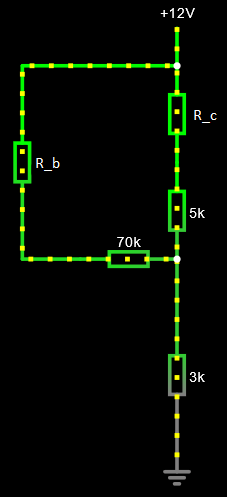

Vemos que Rc y Rb estan en paralelo, por lo que a amabos les llega 12V inicialmente, asi que tenemos dos rutas de caida de tension. 

Sabemos la caida de tension colector-emisor V_CE = 5V, y la caida de tensión en la resistencia de polarización V_E = 3V, entonces por LTK, en el resistor de polarización Rc debe caer una tension de 4V, debido a que es lo que nos falta para que haya una caida de tension de 12V desde la fuente a tierra y asi se respete la LTK. De la misma manera analizamos la ruta de Rb. Lo verificamos calculando:

Vf = 12;
V_Rc = Vf - V_CE - V_E  

V_Rc =      4


V_Rb = Vf - V_BE - V_E

V_Rb =           8.3


teniendo las caidas de tension y conociendo las corrientes que pasan, podemos calcular sus valores de resistencia, y lo verificamos en el simulador:

Rb = V_Rb/I_B

Rb =       830000


Rc = V_Rc/I_C

Rc =         4000